# Eigen-Decomposition & Singular Value Decomposition

Note that the costs of eigen-decomposition and SVD are as

- eigen-decomposition: $9n^3$ if matrix is with size $n\times n$

- SVD: $14mn^2+8n^3$ if matrix is with size $m\times n ~ (m\geq n)$  

Please refer to Nicholas J. Higham, *Functions of Matrices: Theory and Computation* for more detail.

## Fix matrix

The **symmetric **matrix is used.

clc; clear; close all;
addpath('../data')

matrix_size = 200;
sparse_ratio = 0.7;
k = floor(sqrt(matrix_size));

reduce_X = normrnd(0, 1, matrix_size, k);
tmp = quantile(abs(reduce_X(:)), sparse_ratio);
reduce_X(abs(reduce_X)<tmp) = 0.0;
X = reduce_X*reduce_X'; % symmetrization
n_sparse = sum(sum(X == 0));
disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(['The sparse ratio is: ', num2str(round(n_sparse/matrix_size^2, 3))])

The sparse ratio is: 0.253


disp(X(1:5, 1:5))

   15.7335    3.4715    8.5398    2.7333   -0.6581
    3.4715   11.1663    5.3865    4.0525   -3.1410
    8.5398    5.3865   13.7511    8.4360         0
    2.7333    4.0525    8.4360   12.2206   -2.0722
   -0.6581   -3.1410         0   -2.0722   12.3942



## Eigen-decomposition

$X=USU^{-1} = USU^T$ where $U$ is o.n. matrix. Note that Frobenius norm is 2 norm of a matrix.

[U, S] = eig(X);
X_approx = full(U*S*U');

disp(['The Frobenius norm of two matrix is ', num2str(norm(X-X_approx)), '.'])

The Frobenius norm of two matrix is 7.4134e-13.


disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X_approx(1:5, 1:5))

   15.7335    3.4715    8.5398    2.7333   -0.6581
    3.4715   11.1663    5.3865    4.0525   -3.1410
    8.5398    5.3865   13.7511    8.4360    0.0000
    2.7333    4.0525    8.4360   12.2206   -2.0722
   -0.6581   -3.1410    0.0000   -2.0722   12.3942



## Sparse matrix

Usually, the transition matrix is sparse. Hence, using `eigs` might be faster. The Arnoldi iteration is applied.

num_largest_ev = 101;
X_sparse = sparse(X);
[U, S] = eigs(X_sparse, num_largest_ev);
X_approx = full(U*S*U');

disp(['The Frobenius norm from approximation matrix is ', num2str(norm(X-X_approx)), '.'])

The Frobenius norm from approximation matrix is 7.4117e-13.


disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X_approx(1:5, 1:5))

   15.7335    3.4715    8.5398    2.7333   -0.6581
    3.4715   11.1663    5.3865    4.0525   -3.1410
    8.5398    5.3865   13.7511    8.4360    0.0000
    2.7333    4.0525    8.4360   12.2206   -2.0722
   -0.6581   -3.1410    0.0000   -2.0722   12.3942



## Singular value decomposition (SVD)

This is low rank approximation method. Roseland reduced method is based on SVD.

$X=X_rX_r^T=(USV^T)(USV^T)^T = USSU^T$ where reduced matrix $X_r = USV^T$

num_largest_ev = 100;
[U, S, V] = svds(reduce_X, num_largest_ev);

X_approx = full(U*S*S*U');

disp(['The Frobenius norm from SVD matrix is ', num2str(norm(X-X_approx)), '.'])

The Frobenius norm from SVD matrix is 1.831e-12.


disp('The left-top 5-by-5 sub-matrix:')

The left-top 5-by-5 sub-matrix:


disp(X_approx(1:5, 1:5))

   15.7335    3.4715    8.5398    2.7333   -0.6581
    3.4715   11.1663    5.3865    4.0525   -3.1410
    8.5398    5.3865   13.7511    8.4360   -0.0000
    2.7333    4.0525    8.4360   12.2206   -2.0722
   -0.6581   -3.1410   -0.0000   -2.0722   12.3942



## Application of SVD

I use 5, 10, 15, ..., 50 eigenvector to approximate original image.

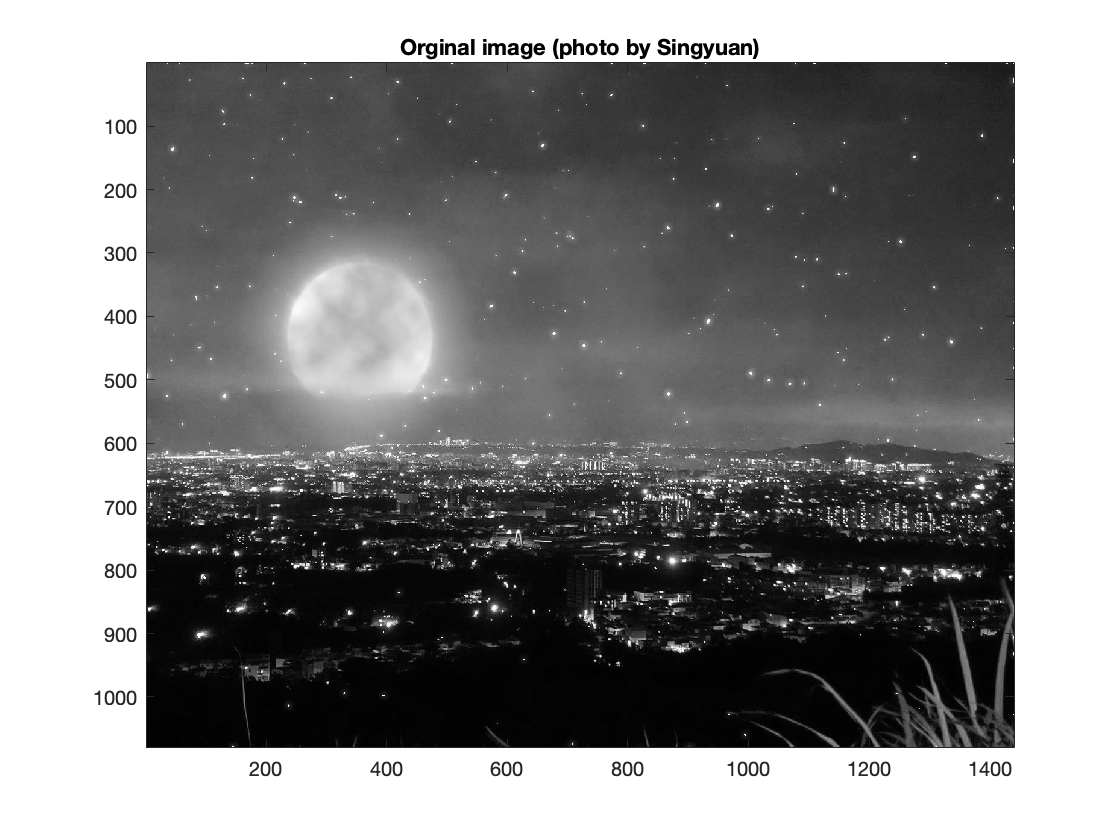

% X = imread('mountain.jpg');
% imshow(X)
% X = double(rgb2gray(X));
% X = X/255.0;
load('mountain_gray.mat')
mountain_gray;
figure
imagesc(mountain_gray);
colormap(gray);
title('Orginal image (photo by Singyuan)')

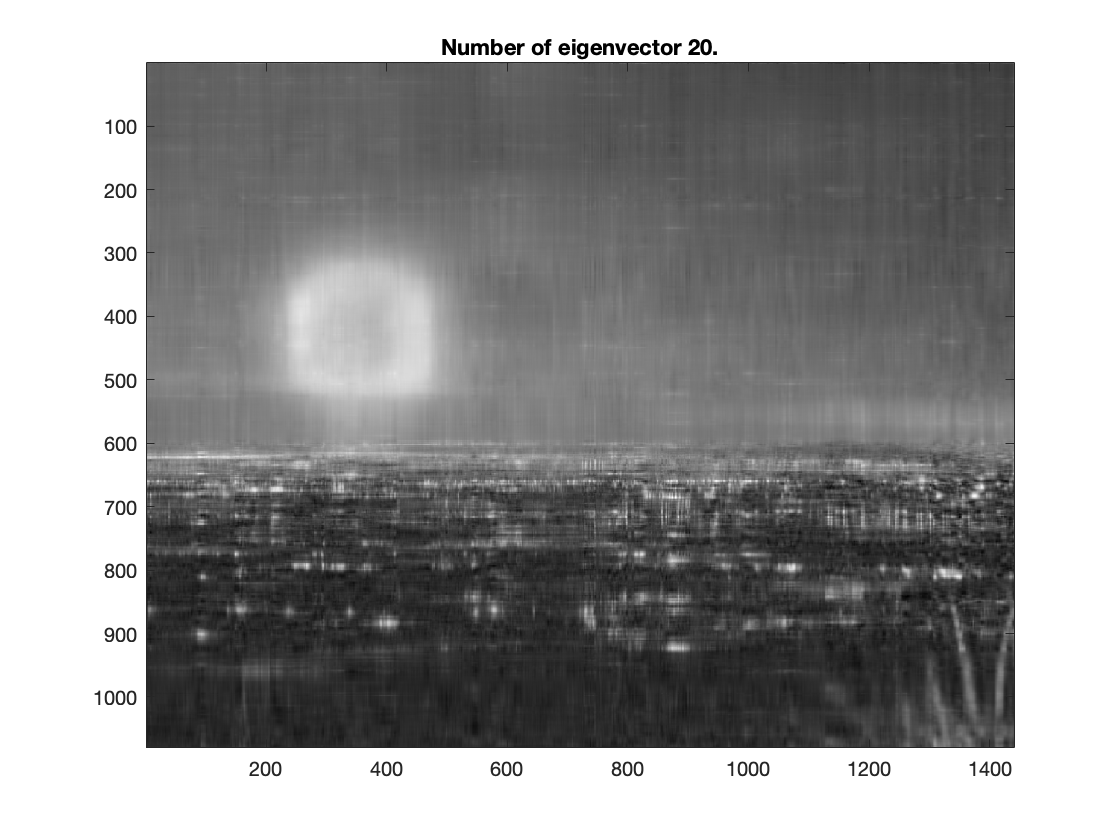

[U, S, V] = svd(mountain_gray);
figure
for i = 5:5:50
    imagesc(U(:, 1:i)*S(1:i, 1:i)*V(:, 1:i)');
    colormap(gray);
    title(['Number of eigenvector ', num2str(i), '.'])
    pause(0.5)
    drawnow
end

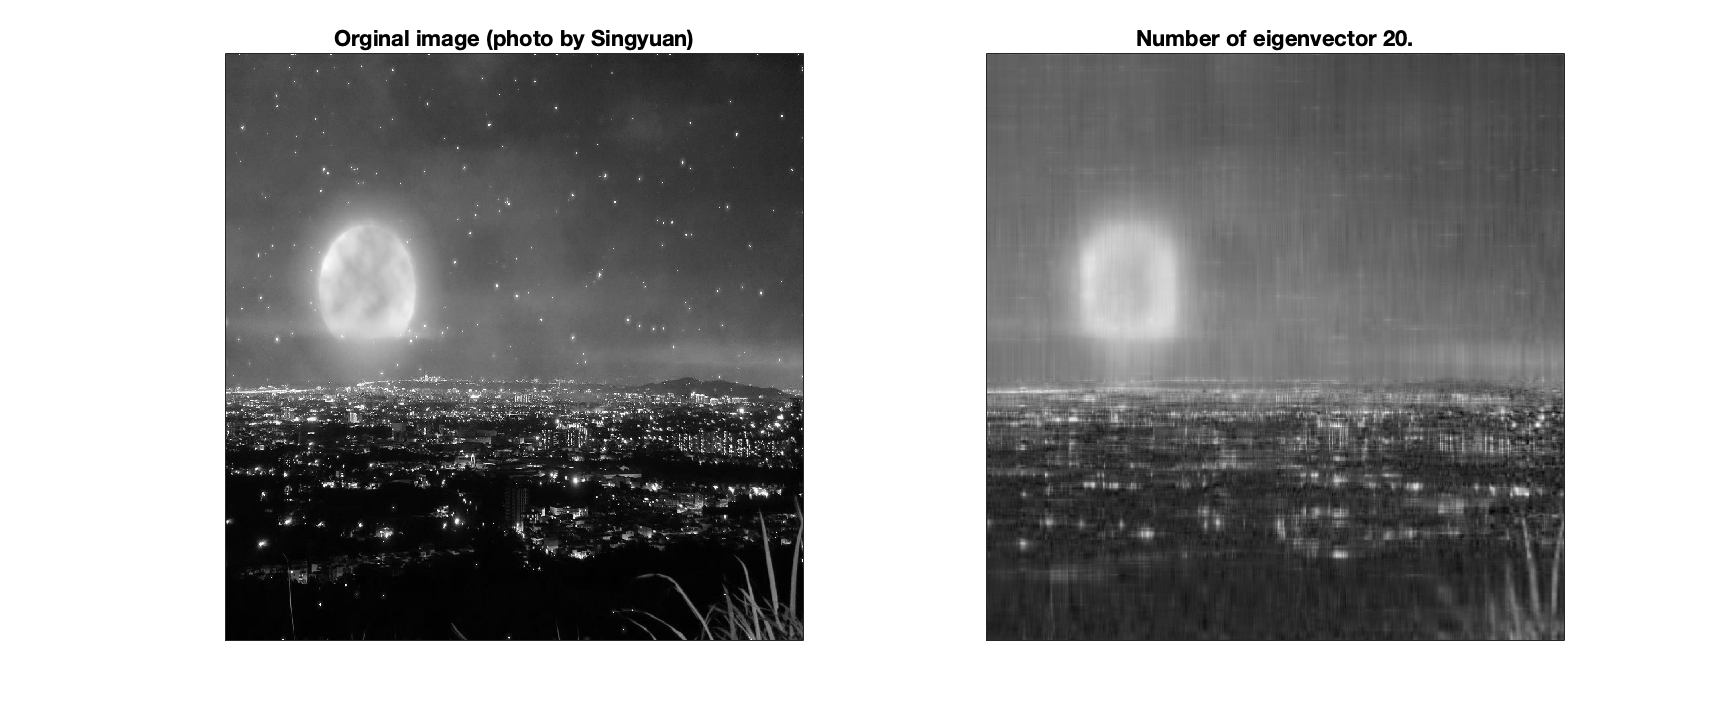

figure
set(gcf,'color','w','units','normalized','position',[0 0.5 0.6 0.4])
subplot(1, 2, 1)
imagesc(mountain_gray);
colormap(gray);
title('Orginal image (photo by Singyuan)')
set(gca,'xtick',[], 'ytick',[])
subplot(1, 2, 2)
imagesc(U(:, 1:20)*S(1:20, 1:20)*V(:, 1:20)');
colormap(gray);
title(['Number of eigenvector ', num2str(20), '.'])
set(gca,'xtick',[], 'ytick',[])